## Standard Continuity Illusion

fs = 44.1e3;
len = .5;
noise_dB = 25;
ramp_dur = .01;

no_noise = horzcat(generate_tone(1000, len, fs, ramp_dur), silence(len/2, fs), generate_tone(1000, len, fs, ramp_dur));
no_noise = set_rms(no_noise, .1);
soundsc(no_noise, fs)
audiowrite("standard_no_noise.wav", no_noise, fs)

signal = horzcat(generate_tone(1000, len, fs, .01), generate_noise(len / 2, fs, ramp_dur, noise_dB), generate_tone(1000, len, fs, .01));
signal = set_rms(signal, .1);
soundsc(signal, fs)
audiowrite("standard.wav", signal, fs)

## Continuity on Random Tone

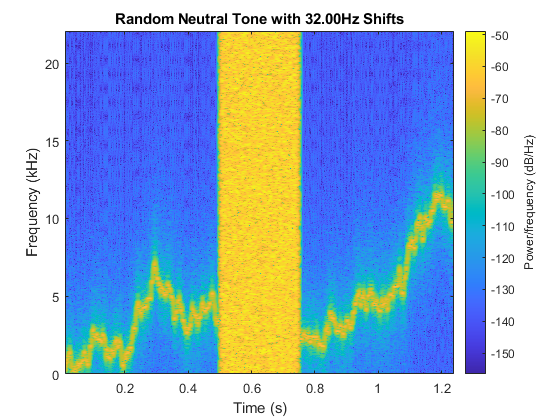

fs = 44.1e3;
len = .5;
noise_dB = 25;
ramp_dur = .01;
up_prob = .5;
shift=16;

for shift=[0, .1, .25, .5, 1, 2, 4, 16, 32]
    [sig_1, sig_2] = generate_rand_tone(1000, up_prob, shift, len, fs, ramp_dur);
    signal = horzcat(sig_1, silence(len / 2, fs), sig_2);
    signal = set_rms(signal, .075);
    audiowrite(sprintf("random_tone-n-%d_shift_no_noise.wav", shift * 100), signal, fs)
    spectrogram(signal, 1024, 1000, 1000, fs, 'yaxis')
    title(sprintf("Random Neutral No Noise Tone with %.2fHz Shifts", shift))
    saveas(gcf, sprintf("random_tone-n-%d_shift_no_noise.png", shift * 100))
    
    signal = horzcat(sig_1, generate_noise(len / 2, fs, ramp_dur, noise_dB), sig_2);
    signal = set_rms(signal, .075);
    audiowrite(sprintf("random_tone-n-%d_shift.wav", shift * 100), signal, fs)
    spectrogram(signal, 1024, 1000, 1000, fs, 'yaxis')
    title(sprintf("Random Neutral Tone with %.2fHz Shifts", shift))
    saveas(gcf, sprintf("random_tone-n-%d_shift.png", shift * 100))
end

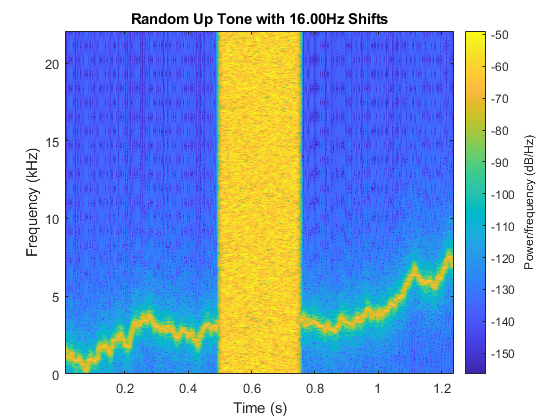

up_prob=.505;
for shift=[0, .1, .25, .5, 1, 2, 4, 16]
    [sig_1, sig_2] = generate_rand_tone(1000, up_prob, shift, len, fs, ramp_dur);
    signal = horzcat(sig_1, silence(len / 2, fs), sig_2);
    signal = set_rms(signal, .075);
    audiowrite(sprintf("random_tone-u-%d_shift_no_noise.wav", shift * 100), signal, fs)
    spectrogram(signal, 1024, 1000, 1000, fs, 'yaxis')
    title(sprintf("Random Up No Noise Tone with %.2fHz Shifts", shift))
    saveas(gcf, sprintf("random_tone-u-%d_shift_no_noise.png", shift * 100))
    
    signal = horzcat(sig_1, generate_noise(len / 2, fs, ramp_dur, noise_dB), sig_2);
    signal = set_rms(signal, .075);
    audiowrite(sprintf("random_tone-u-%d_shift.wav", shift * 100), signal, fs)
    spectrogram(signal, 1024, 1000, 1000, fs, 'yaxis')
    title(sprintf("Random Up Tone with %.2fHz Shifts", shift))
    saveas(gcf, sprintf("random_tone-u-%d_shift.png", shift * 100))
end

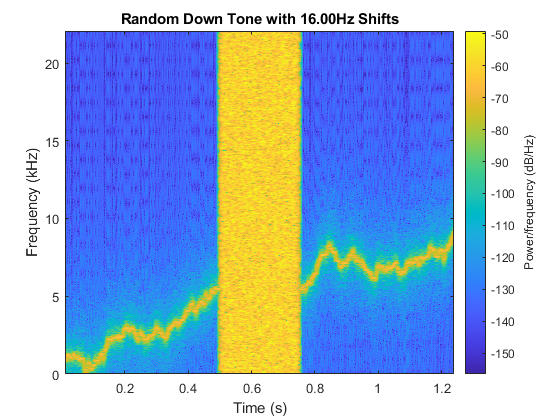

up_prob=.495;
for shift=[0, .1, .25, .5, 1, 2, 4, 16]
    [sig_1, sig_2] = generate_rand_tone(1000, up_prob, shift, len, fs, ramp_dur);
    signal = horzcat(sig_1, silence(len / 2, fs), sig_2);
    signal = set_rms(signal, .075);
    audiowrite(sprintf("random_tone-d-%d_shift_no_noise.wav", shift * 100), signal, fs)
    spectrogram(signal, 1024, 1000, 1000, fs, 'yaxis')
    title(sprintf("Random Down No Noise Tone with %.2fHz Shifts", shift))
    saveas(gcf, sprintf("random_tone-d-%d_shift_no_noise.png", shift * 100))
    
    
    signal = horzcat(sig_1, generate_noise(len / 2, fs, ramp_dur, noise_dB), sig_2);
    signal = set_rms(signal, .075);
    audiowrite(sprintf("random_tone-d-%d_shift.wav", shift * 100), signal, fs)
    spectrogram(signal, 1024, 1000, 1000, fs, 'yaxis')
    title(sprintf("Random Down Tone with %.2fHz Shifts", shift))
    saveas(gcf, sprintf("random_tone-d-%d_shift.png", shift * 100))
end

## Continuity on Linear Frequency Rise Illusion

fs = 44.1e3;
len = .5;
noise_dB = 25;
ramp_dur = .01;

start = 220;
stop = 880;

for offset=0:150:(stop - start)
    up_freqs = generate_linear_freq(start, stop, len, fs);
    up_signal = generate_fm_tone(up_freqs, fs, ramp_dur);
    
    down_freqs = generate_linear_freq(stop - offset, start, (stop - offset - start) / ((stop - start) / len), fs);
    down_signal = generate_fm_tone(down_freqs, fs, ramp_dur);
    
    signal = horzcat(up_signal, silence(len/2, fs), down_signal);
    signal = set_rms(signal, .1);
%     soundsc(signal, fs);
    audiowrite(sprintf("linear_offset-%dHz_no_noise.wav", offset), signal, fs)
    
    signal = horzcat(up_signal, generate_noise(len/2, fs, ramp_dur, noise_dB), down_signal);
    signal = set_rms(signal, .1);
%     soundsc(signal, fs);
    audiowrite(sprintf("linear_offset-%dHz.wav", offset), signal, fs)
end

## Continuity on Exponential Frequency Rise Illusion

fs = 44.1e3;
len = .5;
noise_dB = 25;
ramp_dur = .01;

start = 220;
stop = 1320;

freqs = generate_expo_freq(start, stop, len, fs);

signal = generate_fm_tone(freqs, fs, ramp_dur);
signal = horzcat(signal, silence(len/2, fs), flip(signal));
signal = set_rms(signal, .1);
soundsc(signal, fs);
audiowrite("exponential_no_noise.wav", signal, fs)

signal = generate_fm_tone(freqs, fs, ramp_dur);
signal = horzcat(signal, generate_noise(len / 2, fs, ramp_dur, noise_dB), flip(signal));
signal = set_rms(signal, .1);
soundsc(signal, fs);
audiowrite("exponential.wav", signal, fs)

## Continuity on Sigmoid Frequency Rise Illusion

fs = 44.1e3;
len = .5;
noise_dB = 25;
ramp_dur = .01;

start = 220;
stop = 880;

for rate=.5:.5:2.5
    signal = generate_fm_tone(generate_sig_freq(start, stop, len, fs, rate), fs, ramp_dur);
    signal = horzcat(signal, silence(len/2, fs), flip(signal));
    signal = set_rms(signal, .05);
%     soundsc(signal, fs);
    audiowrite(sprintf("sigmoid-%d_no_noise.wav", rate * 10), signal, fs)
    
    signal = generate_fm_tone(generate_sig_freq(start, stop, len, fs, rate), fs, ramp_dur);
    signal = horzcat(signal, generate_noise(len / 2, fs, ramp_dur, noise_dB), flip(signal));
    signal = set_rms(signal, .05);
%     soundsc(signal, fs);
    audiowrite(sprintf("sigmoid-%d.wav", rate * 10), signal, fs)
end

## Functions

function ramp = on_off_ramp(t, fs, ramp_dur)
    ramp = ones(size(t));
    ramp_dur = floor(fs * ramp_dur);
    ramp(1:ramp_dur) = linspace(0, 1, ramp_dur);
    ramp(end - ramp_dur + 1:end) = linspace(1, 0, ramp_dur);
end

function ramp = off_on_ramp(t, fs, ramp_dur)
    ramp = on_off_ramp(t, fs, ramp_dur);
    ramp = 1 - ramp;
end

function noisy_signal = add_noise(signal, max)
    noise = randn(size(signal));
    noise = set_rms(noise, max);
    noisy_signal = signal + noise;
end

function signal = silence(t_len, fs)
    signal = zeros(1, floor(t_len * fs));
end

function freqs = generate_linear_freq(start_freq, stop_freq, t_len, fs)
    freqs = linspace(start_freq, stop_freq, floor(t_len * fs));
end

function freqs = generate_expo_freq(start_freq, stop_freq, t_len, fs)
    freqs = linspace(log(start_freq), log(stop_freq), floor(t_len * fs));
    freqs = exp(freqs);
end

function freqs = generate_sig_freq(start_freq, stop_freq, t_len, fs, x)
    freqs = linspace(-6, 6, floor(fs * t_len));
    freqs = (stop_freq - start_freq) ./ (1 + exp(-x * freqs)) + start_freq;
end

function signal = generate_fm_tone(freqs, fs, ramp_dur)
    signal = sin(2 * pi * cumsum(1/fs * freqs));
    if (ramp_dur > 0)
        ramp = on_off_ramp(freqs, fs, ramp_dur);
        signal = signal.* ramp;
    end
end

function [first_signal, second_signal] = generate_rand_tone(start_freq, up_prob, shift, t_len, fs, ramp_dur)
    freqs = start_freq * ones(1, floor(2 * t_len * fs));
    r = rand(size(freqs));
    r = (-1 * (r > up_prob)) + (r <= up_prob);
    r = cumsum(r) * shift;
    
    freqs = freqs + r;
    
    signal = generate_fm_tone(freqs, fs, ramp_dur);
    half = ceil(length(signal) / 2);
    first_signal = signal(1:half);
    second_signal = signal(half + 1:end);
end

function signal = generate_tone(freq, t_len, fs, ramp_dur)
    t = linspace(0, t_len, floor(fs * t_len));
    signal = sin(2 * pi * freq * t);
    if (ramp_dur > 0)
        ramp = on_off_ramp(t, fs, ramp_dur);
        signal = signal.* ramp;
    end
end

function signal = generate_noise(t_len, fs, ramp_dur, dB)
    t = linspace(0, t_len, floor(fs * t_len));
    signal = randn(size(t));
    if (ramp_dur > 0)
        ramp = on_off_ramp(t, fs, ramp_dur);
        signal = randn(size(t)) .* ramp;
    end
    
    signal = set_rms(signal, 10^(dB / 20));
end

function wave = set_rms(signal, rms_val)
    multiplier = rms_val / rms(signal);
    wave = signal * multiplier;
end